paramNameValStruct.SimulationMode = 'accelerator';
paramNameValStruct.TimeOut        = 40;
simOut = sim('exp2M_CSVposRef',paramNameValStruct);

simOut.getSimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2022-01-20 10:13:42'
           WallClockTimestampStop: '2022-01-20 10:14:25'
    InitializationElapsedWallTime: 0.5588
         ExecutionElapsedWallTime: 40.0085
       TerminationElapsedWallTime: 2.5416
             TotalElapsedWallTime: 43.1089
                     ProfilerData: 'Profiler is not enabled'


t_f = 10; % end time
opts = delimitedTextImportOptions("NumVariables",4, ...
    "Delimiter",',', ...
    "VariableNames",{'Left hip','Left knee','Right hip','Right knee'}, ...
    "VariableTypes",{'double','double','double','double'}, ...
    "PreserveVariableNames",true);
tabularData = readtable('Data\Gait\Gait_2Joints_02.csv',opts);
sm_t = linspace(0,t_f,size(tabularData,1));
sm_traj = deg2rad(table2array(tabularData));
sm_path = timeseries(sm_traj,sm_t);
save Tests/Exp_2MaxonMotors/exp2Msetup sm_path sm_traj sm_t t_f

p1 = simOut.p1;
Ts = simOut.tout(2);
% create iddata type with inputs and outputs
data1 = iddata(p1.Data(:,2),p1.Data(:,1),Ts,'Name','Motor 1 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 2 poles and no zero
m11 = tfest(data1,2,0); m11.Report.Fit

ans = struct with fields:
    FitPercent: 84.3232
       LossFcn: 4.7217e+03
           MSE: 4.7217e+03
           FPE: 4.7461e+03
           AIC: 2.1849e+04
          AICc: 2.1849e+04
          nAIC: 8.4651
           BIC: 2.1876e+04


% transfer function estimation with 1 pole and no zero
m12 = tfest(data1,1,0); m12.Report.Fit

ans = struct with fields:
    FitPercent: 84.3229
       LossFcn: 4.7219e+03
           MSE: 4.7219e+03
           FPE: 4.7365e+03
           AIC: 2.1845e+04
          AICc: 2.1845e+04
          nAIC: 8.4631
           BIC: 2.1861e+04


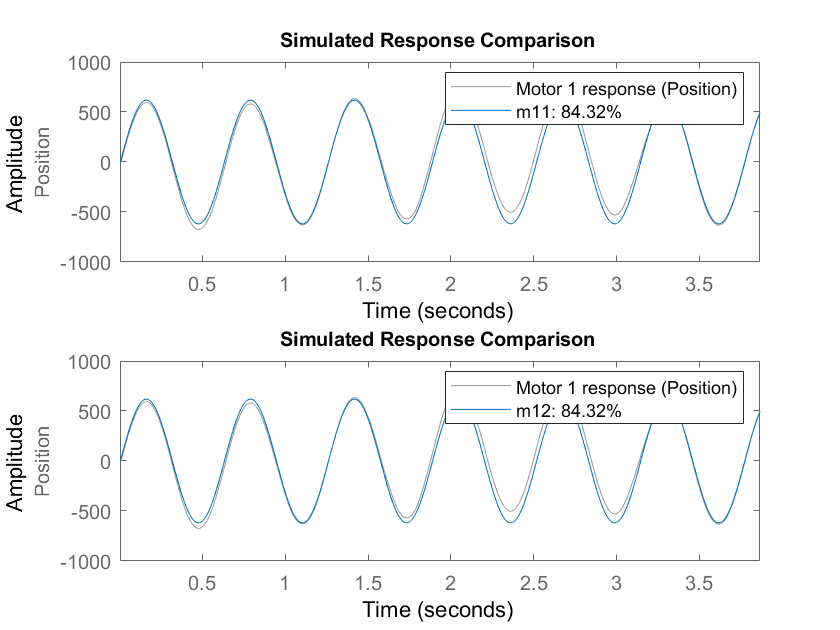

figure
subplot(2,1,1)
compare(data1,m11) % first order model evaluation
subplot(2,1,2)
compare(data1,m12) % second order model evaluation

p2 = simOut.p2;
data2 = iddata(p2.Data(:,2),p2.Data(:,1),Ts,'Name','Motor 2 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 2 poles and no zero
m21 = tfest(data2,2,0); m21.Report.Fit

ans = struct with fields:
    FitPercent: 84.3258
       LossFcn: 4.7195e+03
           MSE: 4.7195e+03
           FPE: 4.7440e+03
           AIC: 2.1848e+04
          AICc: 2.1848e+04
          nAIC: 8.4646
           BIC: 2.1876e+04


% transfer function estimation with 1 pole and no zero
m22 = tfest(data2,1,0); m22.Report.Fit

ans = struct with fields:
    FitPercent: 84.3239
       LossFcn: 4.7207e+03
           MSE: 4.7207e+03
           FPE: 4.7353e+03
           AIC: 2.1844e+04
          AICc: 2.1844e+04
          nAIC: 8.4628
           BIC: 2.1861e+04


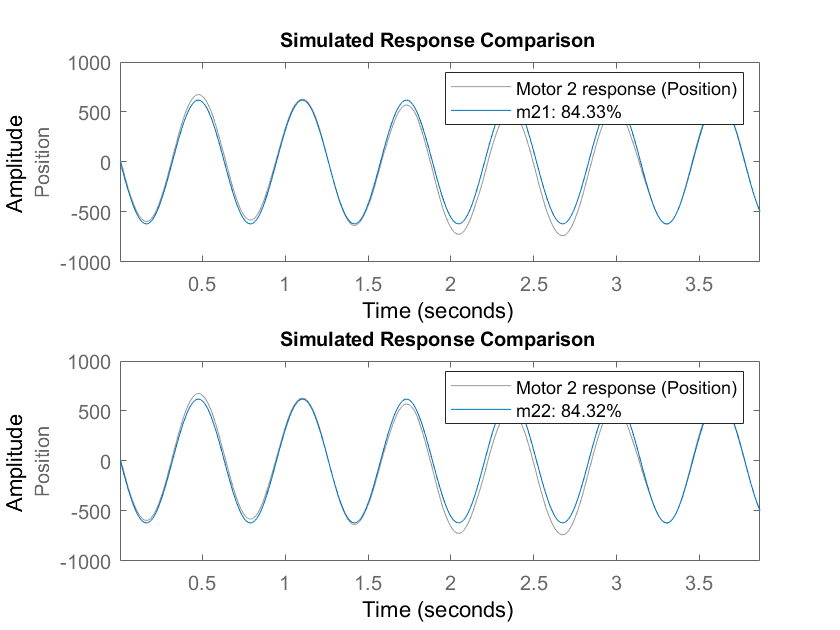

figure
subplot(2,1,1)
compare(data2,m21) % first order model evaluation
subplot(2,1,2)
compare(data2,m22) % second order model evaluation

From the results above, the first order transfer function model has competitive performance compared to second order variation. The first order transfer functions also reduce computation complexity. Thus it provides faster response.

clear m11 m21 data1 data2 opts tabularData
save Data/Exoskeleton/motorModel p1 p2 m12 m22 Ts
model = 'tf2M_CSVposRef_ctrlDesign';
load_system(model)
setActiveConfigSet(model, 'systemIdentification');
save_system(model)
open(model)